clear;
close all;
clc;

## Load the raw data

load('ppg_acc.mat');

## Baseline attenuation: Highpass filter on the PPG and accelerometer signals

For the PPG signal we do not want to filter out the heart rate. Considering a minimal physiological heart rate of 30 bpm (0.5 Hz), we can use a highpass filter at 0.5 Hz. For the accelerometer norm signal, we do not want to filter out the frequencies of rhythmic motion. Considering a very slow walking pace of 1 step/s (1 Hz), the frequency of the arm swinging movement is half of that frequency, i.e. 0.5 Hz, and therefore we can use the same filter as for the PPG signal.

fs = 25;
[b,a] = butter(2, 0.5/(fs/2), 'high');
ppg = filtfilt(b, a, ppg);
accn = filtfilt(b, a, accn);

## Spectrogram of the PPG & accelerometer norm signals

When running, or when suddenly stopping an intense exercise, the heart rate can change quite fast in matter of a few seconds. A window of 10 seconds would be short enough at all times to consider the signal stationary in the window. However, a slightly longer window, e.g. 20 seconds, will also be fine the vast majority of the time, with the advantage of improving the frequency resolution of our spectrogram. It is therefore a good choice.

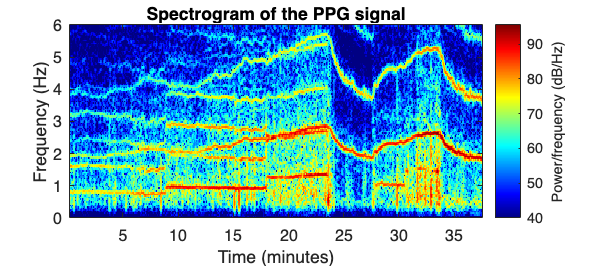

window = round(20*fs);          % Windows of 20 seconds
noverlap = round(0.95*20*fs);   % Overlap of 95%

figure('Units','centimeters','Position',[0,0,25,11],'Color','w');
spectrogram(ppg, window, noverlap, [], fs, 'yaxis');
ylim([0,6]);
colormap('jet');
set(gca, 'clim', [40, max(get(gca, 'clim'))]);
title('Spectrogram of the PPG signal');

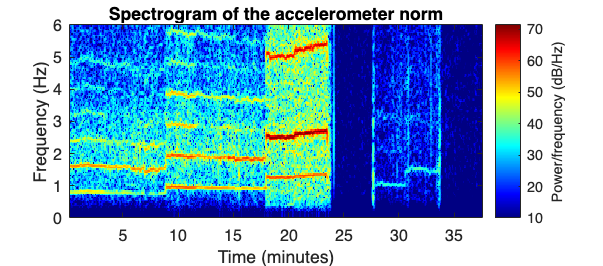


figure('Units','centimeters','Position',[5,5,25,11],'Color','w');
spectrogram(accn, window, noverlap, [], fs, 'yaxis');
ylim([0,6]);
colormap('jet');
set(gca, 'clim', [10, max(get(gca, 'clim'))]);
title('Spectrogram of the accelerometer norm');

## Question 1:

The 7 phases of the protocol take place as follows:

1) walk for the first 9 seconds (T=0 to 9s)

2) run (slow pace) for 9 seconds (T=9 to 18s)

3) run (fast pace) for 6 seconds (T=18 to 24s)

4) rest (recovery) for 3 seconds (T=24 to 28s)

5) bike (slow pace) for 3 seconds (T=28 to 31s)

6) bike (fast pace) for 3 seconds (T=31 to 34s)

7) rest (recovery) for the the last 3.5 seconds (T=34 to 37.5s)

## Question 2:

We can observe that there is one harmonic of our PPG signal, starting at approximately 4 Hz. The fondamental starts at 2 Hz and increases up to 3 Hz. The rest is noise, caused by the movement.

## Question 3:

When biking, the hand is not moving a lot compared to running. Hence we expect the accelerometer norm signal to have less energy during biking sessions compared to running sessions. The accelerometer spectrogram indeed reveals this contrast. 

## Question 4

During the fast running session, the heart rate has a frequency close to the harmonics of the movement. Therefore, trying to remove the signal of the accelerometer by applying a notch filter will also remove the signal of interest.

## Question 5

On the spectrogram of the accelerometer norm, one can read a frequency of 0.8Hz, which corresponds to 48*2 = 96 steps per minute.